% Radius of the area being evaluated, i.e. you may want to look at a 
% radius of 50 mm, but to cover the sides, you expand the area to 55 mm.
% Usually just keep the two equal
rad = 50; 
% Radius of the survey area 
rad_survey = 50;
% Radius of detectable object in mm
r = 5; 
% Resmolution of survey. 
resolution_mm = 1;
% Distance to the plane - Should be between 80 and 60 mm for the survey
dist2plane = 75;

%--------------------------

% Maximum number of pictures
numPictures = 30;
% Iterations per picture
numIterations = 1000;

% If it is desired to input a priori data, you can do so here. 
% A benefit could be if you want to ensure certain positions are filled out
% alreay. The script then finds n new pictures corresponding 
% to numPictures - the amount of rows in rot_apriori.
rot_apriori = [0, 0, 0];


% Find the origin and unit vectors of the SLI points in the sparse array
[O_sparse, unit_vec_sparse, ~, ~] = analyseData();
% Locate
[Nref, pos1, pos2, pos3, p2, p_xray, h_xray, pivot_point, uv_xray] = PIXLmodel(dist2plane);

CP1 = drawCircle(rad, pos1,Nref,'r', 2);
CPsurvey = drawCircle(rad_survey, pos1,Nref,'r', 2);
CP2 = drawCircle(rad,pos2,Nref,'g', 2);
CP3 = drawCircle(rad,pos3,Nref,'g', 2);
CP = [CP1; CP2];
k = convhull(CP(1:end-1, 1), CP(1:end-1, 2));
CP = unique(CP(k, 1:2), 'rows');

%Step 1: Find the unweighted mean of the vertices:
cx = mean(CP(:, 1));
cy = mean(CP(:, 2));

%Step 2: Find the angles:
angles = atan2(CP(:, 2) - cy, CP(:, 1) - cx);

%Step 3: Find the correct sorted order:
[~, order] = sort(angles);

%Step 4: Reorder the coordinates:
CP = CP(order, 1:2);

steps = 10; % Coordinates can be in steps of 1/10th of a degree
roll = [-6, 10].*steps; % Rotation around x-axis
pitch = [-6, 7].*steps; % Rotation around y-axis
yaw =   [-0, 0].*steps; % Rotation around z-axis

% Set values
[area_eval, area_best, old_area_best] = deal(0);
area_total = polyarea(CP(:, 1), CP(:, 2));
rot = [0, 0, 0];
rot_best = rot;
[I_best, I] = deal([]);

%--------------------------

c = distinguishable_colors(numPictures);
view = zeros(numPictures, 1);
%view(1) = 1; % view last two

% Rotation to align with base-frame
best_angle_x = 18; % 18.27;
best_angle_y = 0;  % -0.38;
best_angle_z = 0;  % 0.2700;

Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];

% Translate to p2
T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
% Translate to nominal plane
T_nominal = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];

% Rotate circle from MCC frame to base frame
newCP = zeros(size(CP1, 1), 3);
newCP_survey = zeros(size(CP1, 1), 3);
for k = 1:size(CP1, 1)
    nCP = T_nominal^-1*T_p2*Rc*T_p2^-1*[CP1(k, 1:3), 1]';
    newCP(k, :) = nCP(1:3);
    nCP = T_nominal^-1*T_p2*Rc*T_p2^-1*[CPsurvey(k, 1:3), 1]';
    newCP_survey(k, :) = nCP(1:3);
end

% Find calculate the rotated SLI points of the a priori data
I_apriori = [];
for i = 1:size(rot_apriori)
    I_sparse = reprojectSLI(p_xray, unit_vec_sparse, p2, h_xray, pivot_point, pos1, rot_apriori(i, :), c(i, :), view(i));
    I_apriori = [I_apriori; [[I_sparse, i*ones(size(I_sparse, 1), 1)]]];
end

%--------------------------

area_dist = zeros(numIterations, size(size(rot_apriori, 1) + 1:numPictures, 1));
time = zeros(size(size(rot_apriori, 1) + 1:numPictures, 1), 1);
for s = size(rot_apriori, 1) + 1:numPictures
    fprintf('Number of elements: %i\n', s); 
    if(area_best >= 100)
        fprintf('Everything covered at picture %i!\n', s - 1); 
        break;
    end
    tic
    for m = 1:numIterations    
        
        % Generate a set of rotation coordinates and test if they
        % are non-unique
        while(true)
            rot =  [rot_apriori; [randi(roll, 1, 1), randi(pitch, 1, 1), randi(yaw, 1, 1)]./steps];
            if(isequal(unique(rot, 'rows'), sortrows(rot)))
                break;
            end
        end
        % Project the data from the newly generated rotation vector
        I = [];
        for i = size(rot_apriori, 1) + 1:s
            I_sparse = reprojectSLI(O_sparse, unit_vec_sparse, p2, h_xray, pivot_point, pos1, rot(i, :), c(i, :), view(i));
            I = [I; [[I_sparse, i*ones(size(I_sparse, 1), 1)]]];
        end
        % Add it to the a priori data
        I = [I_apriori; I];
                    
        % Calculate the area of both circles. We evaluate based area_eval
        % but always save area_save
        area_eval = calculateArea(rad, r, resolution_mm, I, 0);
        area_save = calculateArea(rad_survey, r, resolution_mm, I, 0);
        
        % If a rotation vector yields a better area coverage, save the
        % parameters
        if(area_eval > area_best)
            rot_best = rot;
            area_best = area_eval;
            I_best = I;
        end
        
        area_dist(m, s) = area_save;
        if(old_area_best < area_best) 
            fprintf('Best coverage at iteration (%i): %f\n', m, area_best); 
        end
        old_area_best = area_best;
    end    
    % The best projected SLI points from every new picture gets added to
    % the a priori data
    I_apriori = I_best;
    rot_apriori = rot_best;
    time(s) = toc;
    fprintf('Elapsed time is %3f seconds\n', time(s))
    fprintf('Total elapsed time is %i minute(s) and %3f second(s)\n', floor(sum(time)/60), mod(sum(time), 60))
end

Number of elements: 2


Best coverage at iteration (1): 18.313099
Best coverage at iteration (2): 23.220447
Best coverage at iteration (7): 26.900958
Best coverage at iteration (51): 27.067093
Best coverage at iteration (89): 28.127796
Best coverage at iteration (103): 29.316294
Best coverage at iteration (416): 29.329073


Elapsed time is 1.076595 seconds


Total elapsed time is 0 minute(s) and 1.076595 second(s)


Number of elements: 3


Best coverage at iteration (1): 36.051118
Best coverage at iteration (7): 36.664537
Best coverage at iteration (8): 37.827476
Best coverage at iteration (11): 40.830671
Best coverage at iteration (196): 40.856230
Best coverage at iteration (255): 41.584665
Best coverage at iteration (330): 41.725240
Best coverage at iteration (335): 41.776358
Best coverage at iteration (373): 42.095847
Best coverage at iteration (697): 42.300319


Elapsed time is 1.317471 seconds


Total elapsed time is 0 minute(s) and 2.394067 second(s)


Number of elements: 4


Best coverage at iteration (1): 48.255591
Best coverage at iteration (2): 48.958466
Best coverage at iteration (4): 49.482428
Best coverage at iteration (6): 52.920128
Best coverage at iteration (46): 54.734824
Best coverage at iteration (871): 55.718850


Elapsed time is 1.583476 seconds


Total elapsed time is 0 minute(s) and 3.977543 second(s)


Number of elements: 5


Best coverage at iteration (1): 58.785942
Best coverage at iteration (2): 61.354633
Best coverage at iteration (3): 62.530351
Best coverage at iteration (186): 62.581470
Best coverage at iteration (193): 62.837061
Best coverage at iteration (217): 63.054313
Best coverage at iteration (374): 63.731629
Best coverage at iteration (409): 63.936102


Elapsed time is 1.906475 seconds


Total elapsed time is 0 minute(s) and 5.884018 second(s)


Number of elements: 6


Best coverage at iteration (1): 67.731629
Best coverage at iteration (2): 68.063898
Best coverage at iteration (35): 68.996805
Best coverage at iteration (64): 70.274760
Best coverage at iteration (745): 70.964856


Elapsed time is 2.318904 seconds


Total elapsed time is 0 minute(s) and 8.202922 second(s)


Number of elements: 7


Best coverage at iteration (1): 73.418530
Best coverage at iteration (3): 74.108626
Best coverage at iteration (10): 74.274760
Best coverage at iteration (18): 75.271565
Best coverage at iteration (36): 75.309904
Best coverage at iteration (175): 75.361022
Best coverage at iteration (189): 75.769968
Best coverage at iteration (293): 75.923323
Best coverage at iteration (774): 76.140575


Elapsed time is 2.695950 seconds


Total elapsed time is 0 minute(s) and 10.898872 second(s)


Number of elements: 8


Best coverage at iteration (1): 77.559105
Best coverage at iteration (2): 78.338658
Best coverage at iteration (4): 79.591054
Best coverage at iteration (12): 79.987220
Best coverage at iteration (30): 80.383387


Elapsed time is 2.748560 seconds


Total elapsed time is 0 minute(s) and 13.647432 second(s)


Number of elements: 9


Best coverage at iteration (1): 82.261981
Best coverage at iteration (2): 82.619808
Best coverage at iteration (6): 83.348243
Best coverage at iteration (37): 83.450479
Best coverage at iteration (76): 83.565495
Best coverage at iteration (135): 83.706070
Best coverage at iteration (177): 83.808307
Best coverage at iteration (235): 83.948882
Best coverage at iteration (255): 84.012780
Best coverage at iteration (256): 84.153355
Best coverage at iteration (454): 84.357827


Elapsed time is 3.271920 seconds


Total elapsed time is 0 minute(s) and 16.919352 second(s)


Number of elements: 10


Best coverage at iteration (1): 84.856230
Best coverage at iteration (4): 85.367412
Best coverage at iteration (5): 85.840256
Best coverage at iteration (7): 86.338658
Best coverage at iteration (11): 86.824281
Best coverage at iteration (23): 86.900958
Best coverage at iteration (66): 87.667732
Best coverage at iteration (83): 87.795527
Best coverage at iteration (136): 87.808307


Elapsed time is 3.570548 seconds


Total elapsed time is 0 minute(s) and 20.489900 second(s)


Number of elements: 11


Best coverage at iteration (1): 89.277955
Best coverage at iteration (6): 89.431310
Best coverage at iteration (26): 89.699681
Best coverage at iteration (35): 89.993610
Best coverage at iteration (743): 90.249201


Elapsed time is 3.776085 seconds


Total elapsed time is 0 minute(s) and 24.265984 second(s)


Number of elements: 12


Best coverage at iteration (1): 91.437700
Best coverage at iteration (7): 91.821086
Best coverage at iteration (31): 91.897764
Best coverage at iteration (281): 91.923323
Best coverage at iteration (575): 92.012780
Best coverage at iteration (689): 92.089457


Elapsed time is 4.042130 seconds


Total elapsed time is 0 minute(s) and 28.308114 second(s)


Number of elements: 13


Best coverage at iteration (1): 93.150160
Best coverage at iteration (77): 93.380192
Best coverage at iteration (95): 93.392971
Best coverage at iteration (115): 93.495208
Best coverage at iteration (298): 93.623003
Best coverage at iteration (336): 93.635783
Best coverage at iteration (532): 93.712460
Best coverage at iteration (609): 93.929712


Elapsed time is 4.388737 seconds


Total elapsed time is 0 minute(s) and 32.696851 second(s)


Number of elements: 14


Best coverage at iteration (1): 94.773163
Best coverage at iteration (6): 95.194888
Best coverage at iteration (245): 95.207668
Best coverage at iteration (298): 95.246006


Elapsed time is 4.715315 seconds


Total elapsed time is 0 minute(s) and 37.412166 second(s)


Number of elements: 15


Best coverage at iteration (1): 95.361022
Best coverage at iteration (2): 95.744409
Best coverage at iteration (7): 96.268371
Best coverage at iteration (69): 96.306709
Best coverage at iteration (155): 96.357827
Best coverage at iteration (204): 96.383387
Best coverage at iteration (372): 96.421725
Best coverage at iteration (470): 96.460064
Best coverage at iteration (618): 96.498403


Elapsed time is 5.070951 seconds


Total elapsed time is 0 minute(s) and 42.483117 second(s)


Number of elements: 16


Best coverage at iteration (1): 96.511182
Best coverage at iteration (2): 96.996805
Best coverage at iteration (16): 97.162939
Best coverage at iteration (49): 97.214058
Best coverage at iteration (179): 97.367412
Best coverage at iteration (525): 97.405751


Elapsed time is 5.388597 seconds


Total elapsed time is 0 minute(s) and 47.871714 second(s)


Number of elements: 17


Best coverage at iteration (2): 97.469649
Best coverage at iteration (3): 97.623003
Best coverage at iteration (6): 97.763578
Best coverage at iteration (8): 97.776358
Best coverage at iteration (11): 97.904153
Best coverage at iteration (83): 97.916933
Best coverage at iteration (160): 97.980831
Best coverage at iteration (212): 98.044728
Best coverage at iteration (253): 98.083067
Best coverage at iteration (397): 98.095847


Elapsed time is 5.717594 seconds


Total elapsed time is 0 minute(s) and 53.589308 second(s)


Number of elements: 18


Best coverage at iteration (3): 98.198083
Best coverage at iteration (5): 98.236422
Best coverage at iteration (8): 98.543131
Best coverage at iteration (52): 98.581470
Best coverage at iteration (281): 98.683706
Best coverage at iteration (674): 98.773163
Best coverage at iteration (835): 98.785942


Elapsed time is 6.124680 seconds


Total elapsed time is 0 minute(s) and 59.713988 second(s)


Number of elements: 19


Best coverage at iteration (2): 99.015974
Best coverage at iteration (13): 99.028754
Best coverage at iteration (110): 99.041534
Best coverage at iteration (117): 99.054313
Best coverage at iteration (158): 99.079872
Best coverage at iteration (374): 99.118211
Best coverage at iteration (582): 99.143770
Best coverage at iteration (833): 99.156550


Elapsed time is 7.133328 seconds


Total elapsed time is 1 minute(s) and 6.847316 second(s)


Number of elements: 20


Best coverage at iteration (1): 99.194888
Best coverage at iteration (2): 99.220447
Best coverage at iteration (3): 99.297125
Best coverage at iteration (5): 99.348243
Best coverage at iteration (14): 99.399361
Best coverage at iteration (324): 99.412141
Best coverage at iteration (355): 99.424920
Best coverage at iteration (705): 99.437700
Best coverage at iteration (801): 99.450479


Elapsed time is 7.812280 seconds


Total elapsed time is 1 minute(s) and 14.659596 second(s)


Number of elements: 21


Best coverage at iteration (2): 99.476038
Best coverage at iteration (4): 99.514377
Best coverage at iteration (6): 99.642173
Best coverage at iteration (72): 99.654952
Best coverage at iteration (76): 99.667732
Best coverage at iteration (111): 99.680511
Best coverage at iteration (378): 99.693291
Best coverage at iteration (464): 99.706070


Elapsed time is 7.560062 seconds


Total elapsed time is 1 minute(s) and 22.219658 second(s)


Number of elements: 22


Best coverage at iteration (2): 99.846645


Elapsed time is 7.202069 seconds


Total elapsed time is 1 minute(s) and 29.421727 second(s)


Number of elements: 23


Best coverage at iteration (2): 99.884984
Best coverage at iteration (10): 99.923323


Elapsed time is 7.391498 seconds


Total elapsed time is 1 minute(s) and 36.813225 second(s)


Number of elements: 24


Best coverage at iteration (3): 99.948882
Best coverage at iteration (33): 99.961661
Best coverage at iteration (80): 99.987220


Elapsed time is 7.735935 seconds


Total elapsed time is 1 minute(s) and 44.549160 second(s)


Number of elements: 25


Best coverage at iteration (16): 100.000000


Elapsed time is 8.318094 seconds


Total elapsed time is 1 minute(s) and 52.867254 second(s)


Number of elements: 26


Everything covered at picture 25!



% Save the position of the X-ray on the survey area
pos_xy = [];
for k = 1:size(rot_best, 1)
    pos_xy(k, :) = [reprojectSLI(p_xray, [-Nref, 0], p2, h_xray, pivot_point, pos1, rot(k, :), 'r', 0), k];
end

area_best = 100

rot_best

rot_best =          0         0         0
    2.9000   -1.1000         0
    3.9000    0.7000         0
    0.8000   -1.0000         0
    1.9000   -2.6000         0
   -0.4000   -3.4000         0
    5.2000   -4.7000         0
    5.5000    0.9000         0
   -0.7000   -1.6000         0
    8.4000    2.2000         0


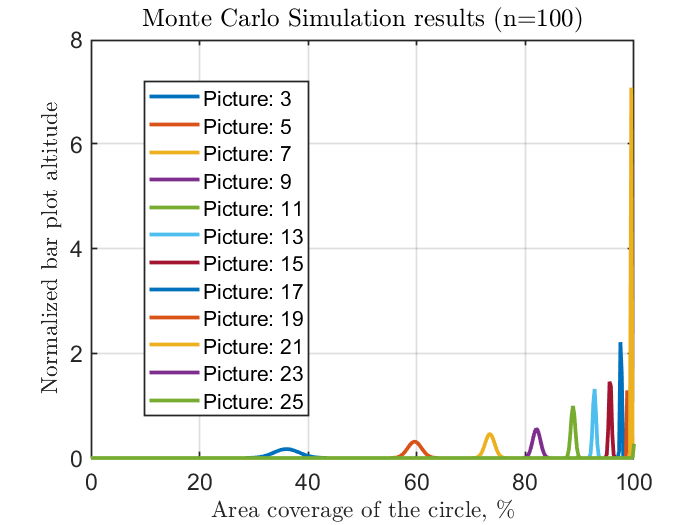

clf
figure(55)
hold on
y = -0:0.25:100;
for i_s = 3:2:size(area_dist, 2)
    mu = mean(area_dist(:, i_s));
    sigma = std(area_dist(:, i_s));
    f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
    legend('Location', 'best')
    plot(y,f,'LineWidth',2.25,'DisplayName',append('Picture: ', num2str(i_s)))
end
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('Monte Carlo Simulation results (n=100)','interpreter','latex', 'FontSize', 15)
xlabel(['Area coverage of the circle, $\%$'],'interpreter','latex', 'FontSize', 14)
ylabel('Normalized bar plot altitude','interpreter','latex', 'FontSize', 14)
grid on
box on

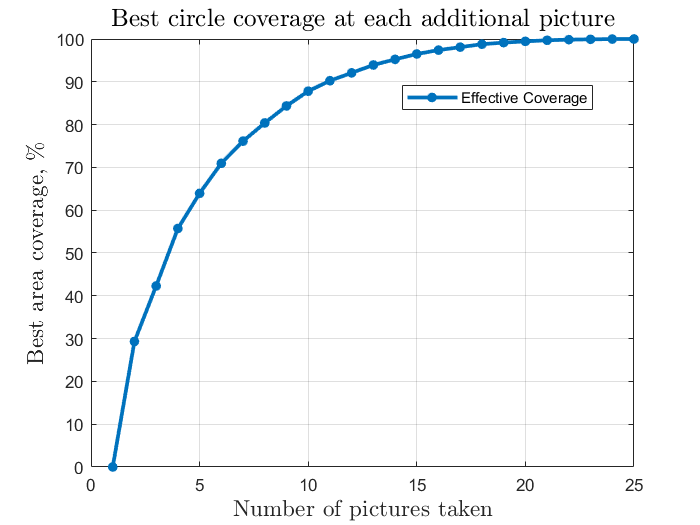

clf
figure(65)
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
plot(max(area_dist), '.-','MarkerSize', 20,'LineWidth',2.25)
title('Best circle coverage at each additional picture','interpreter','latex', 'FontSize', 15)
xlabel('Number of pictures taken','interpreter','latex', 'FontSize', 14)
ylabel(['Best area coverage, $\%$'],'interpreter','latex', 'FontSize', 14)
grid on
box on
legend('Effective Coverage', 'Location', 'best')

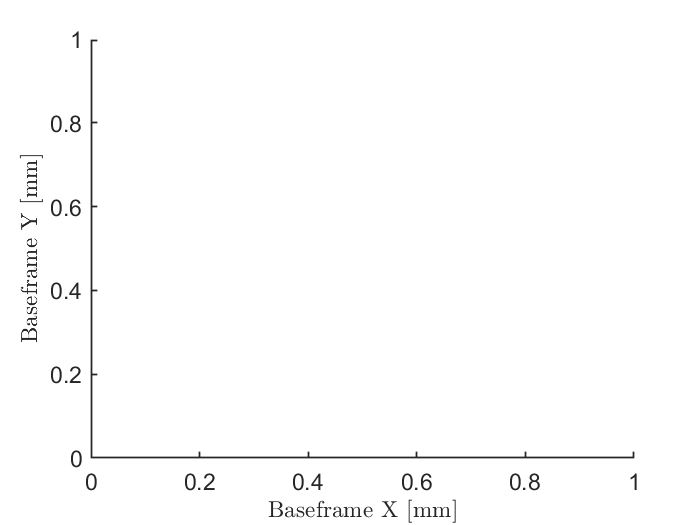

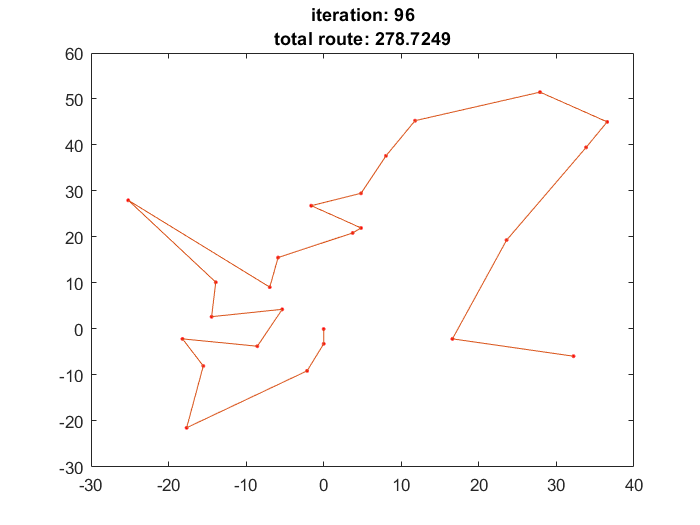

sortedCoords =    32.2086   -5.9164
   16.5964   -2.1426
   23.5796   19.3368
   33.8317   39.4949
   36.5412   45.0220
   27.8886   51.4930
   11.7724   45.2851
    8.0245   37.6395
    4.8140   29.5108
   -1.6046   26.8107


sortedCoords_ID =     23
    25
    11
    24
    21
    16
    10
    14
     8
    18


clf
prompt = "How many pictures would you like to use? ";
n_pictures = input(prompt);


[sortedCoords, sortedCoords_ID, ~] = solveTSP([pos_xy(1:n_pictures, 1:2); [0, 0]], true)

sortedCoords = flip(sortedCoords(1:end-1, :))

sortedCoords =          0   -0.0000
         0   -3.2092
   -2.1394   -9.0953
  -17.6694  -21.4642
  -15.5238   -8.0348
  -18.2061   -2.1432
   -8.5598   -3.7456
   -5.3490    4.2797
  -14.4515    2.6773
  -13.9155   10.1763


sortedCoords_ID = flip(sortedCoords_ID(1:end-1, :))

sortedCoords_ID =      1
    15
    12
    19
    17
     6
     9
     4
    13
     5


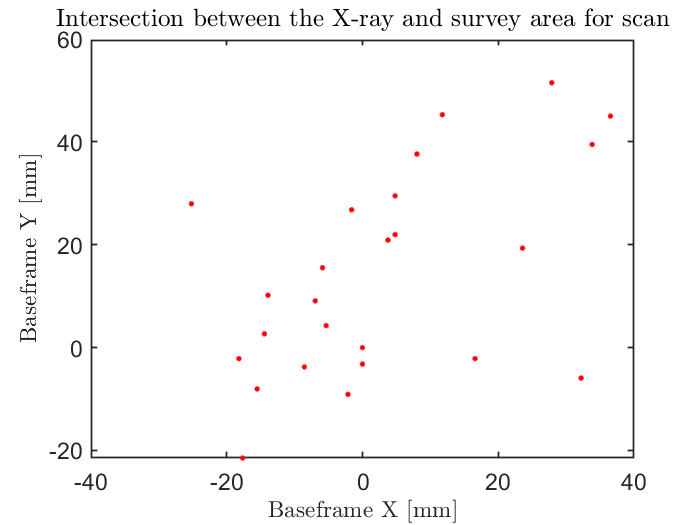


T = array2table([pos_xy(:, 5), pos_xy(:, 1:2)]);
T.Properties.VariableNames(1:3) = {'N','posX','posY'};
writetable(T,'file1.csv');

clf
figure(4)
plot(pos_xy(1:n_pictures, 1), pos_xy(1:n_pictures, 2), 'r.', 'MarkerSize', 10)
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('Intersection between the X-ray and survey area for scan','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)

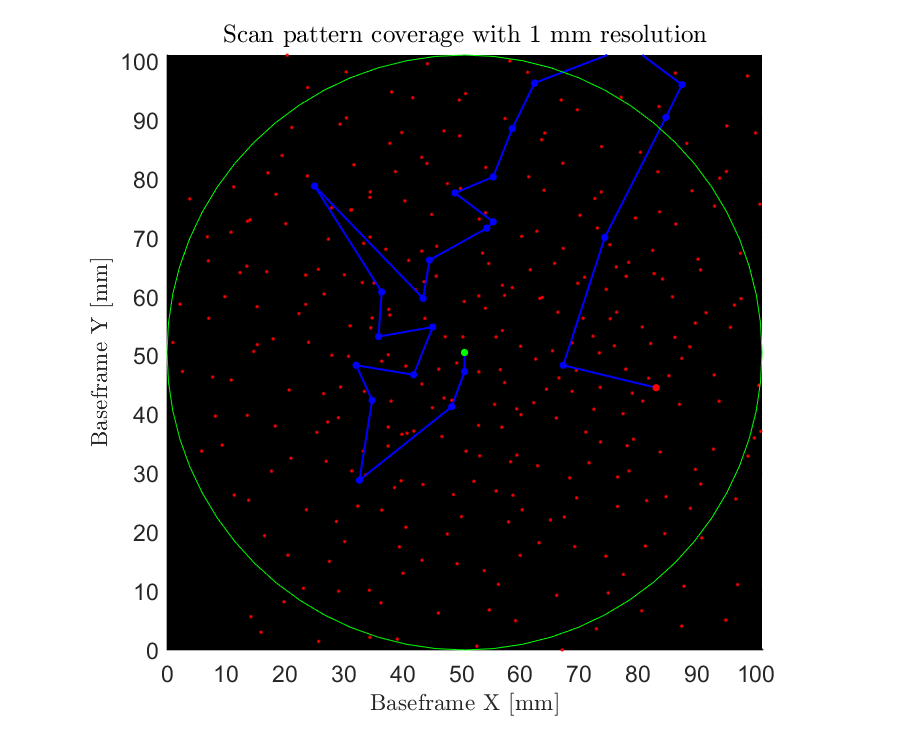

clf
figure(101)
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('Scan pattern coverage with $1~\mathrm{mm}$ resolution','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
filename = 'scan_pattern.gif';

N = 2*rad/resolution_mm;
N = N + 1;

N_survey = 2*rad_survey/resolution_mm;
N_survey = N_survey + 1;
area_dist_sorted = zeros(size(rot_best(1:n_pictures, :), 1), 1);
hold on
for n = 1:size(rot_best(1:n_pictures, :), 1)
    vals = I_best(ismember(I_best(:, 5), sortedCoords_ID(1:n)), 1:2);


    canvas = zeros(N, N);
    cen_canvas = floor(N/2 + 1); % center of the circle in the matrix (both x and y)
    Rcanvas = floor(N_survey/2); % radius of the circle in the matrix

    
    [x,y]=meshgrid(1:N);
    canvas((x - cen_canvas).^2 + (y - cen_canvas).^2 < Rcanvas^2) = 1;
    area_circ = sum(canvas, 'all');
    
    for i = 1:size(vals, 1)
        canvas((x - (N*(rad + vals(i, 1))/(2*rad))).^2 + (y - (N*(rad + vals(i, 2))/(2*rad))).^2 < (N/(2*rad/r))^2) = 0;
    end
    
    imagesc((0:N), (0:N), canvas);          % Plot the image
    colormap(gray);                              % Use a gray colormap
    axis equal                                   % Make axes grid sizes equal
    set(gca, 'XTick', 0:10:(N), 'YTick', 0:10:(N), ...  % Change some axes properties
             'XLim', [0 N], 'YLim', [0 N], ...
             'GridLineStyle', '-', 'XGrid', 'on', 'YGrid', 'on');
    
    hold on
    % SLI points on surface
    plot(N.*(rad + vals(:, 1))./(2*rad), N.*(rad + vals(:, 2))./(2*rad), 'r.', 'MarkerSize', 5, 'LineWidth', 5)
    %Trace path
    plot(N.*(rad + pos_xy(sortedCoords_ID(1:n), 1))./(2*rad), N.*(rad + pos_xy(sortedCoords_ID(1:n), 2))./(2*rad), 'b.-', 'MarkerSize', 15, 'LineWidth', 1.2)
    
    % First and last point
    plot(N.*(rad + pos_xy(sortedCoords_ID(1), 1))./(2*rad), N.*(rad + pos_xy(sortedCoords_ID(1), 2))./(2*rad), 'g.-', 'MarkerSize', 15, 'LineWidth', 1.2)
    plot(N.*(rad + pos_xy(sortedCoords_ID(n), 1))./(2*rad), N.*(rad + pos_xy(sortedCoords_ID(n), 2))./(2*rad), 'r.-', 'MarkerSize', 15, 'LineWidth', 1.2)
    
    % Bigger Circle
    plot(N.*(rad + newCP(:, 1))./(2*rad), N.*(rad + newCP(:, 2))./(2*rad), 'b-', 'MarkerSize', 5)
    % Survey Circle
    displacement = mean(N.*(rad + newCP(:, 1:2))./(2*rad)) - mean(N_survey.*(rad_survey + newCP_survey(:, 1:2))./(2*rad_survey));
    plot(displacement(1) + N_survey.*(rad_survey + newCP_survey(:, 1))./(2*rad_survey), displacement(2) + N_survey.*(rad_survey + newCP_survey(:, 2))./(2*rad_survey), 'g-', 'MarkerSize', 5)
    
    drawnow
    frame = getframe;
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,128);
    if n == 1;
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
    area_dist_sorted(n) = (1 - sum(canvas, 'all')/area_circ) * 100;
end

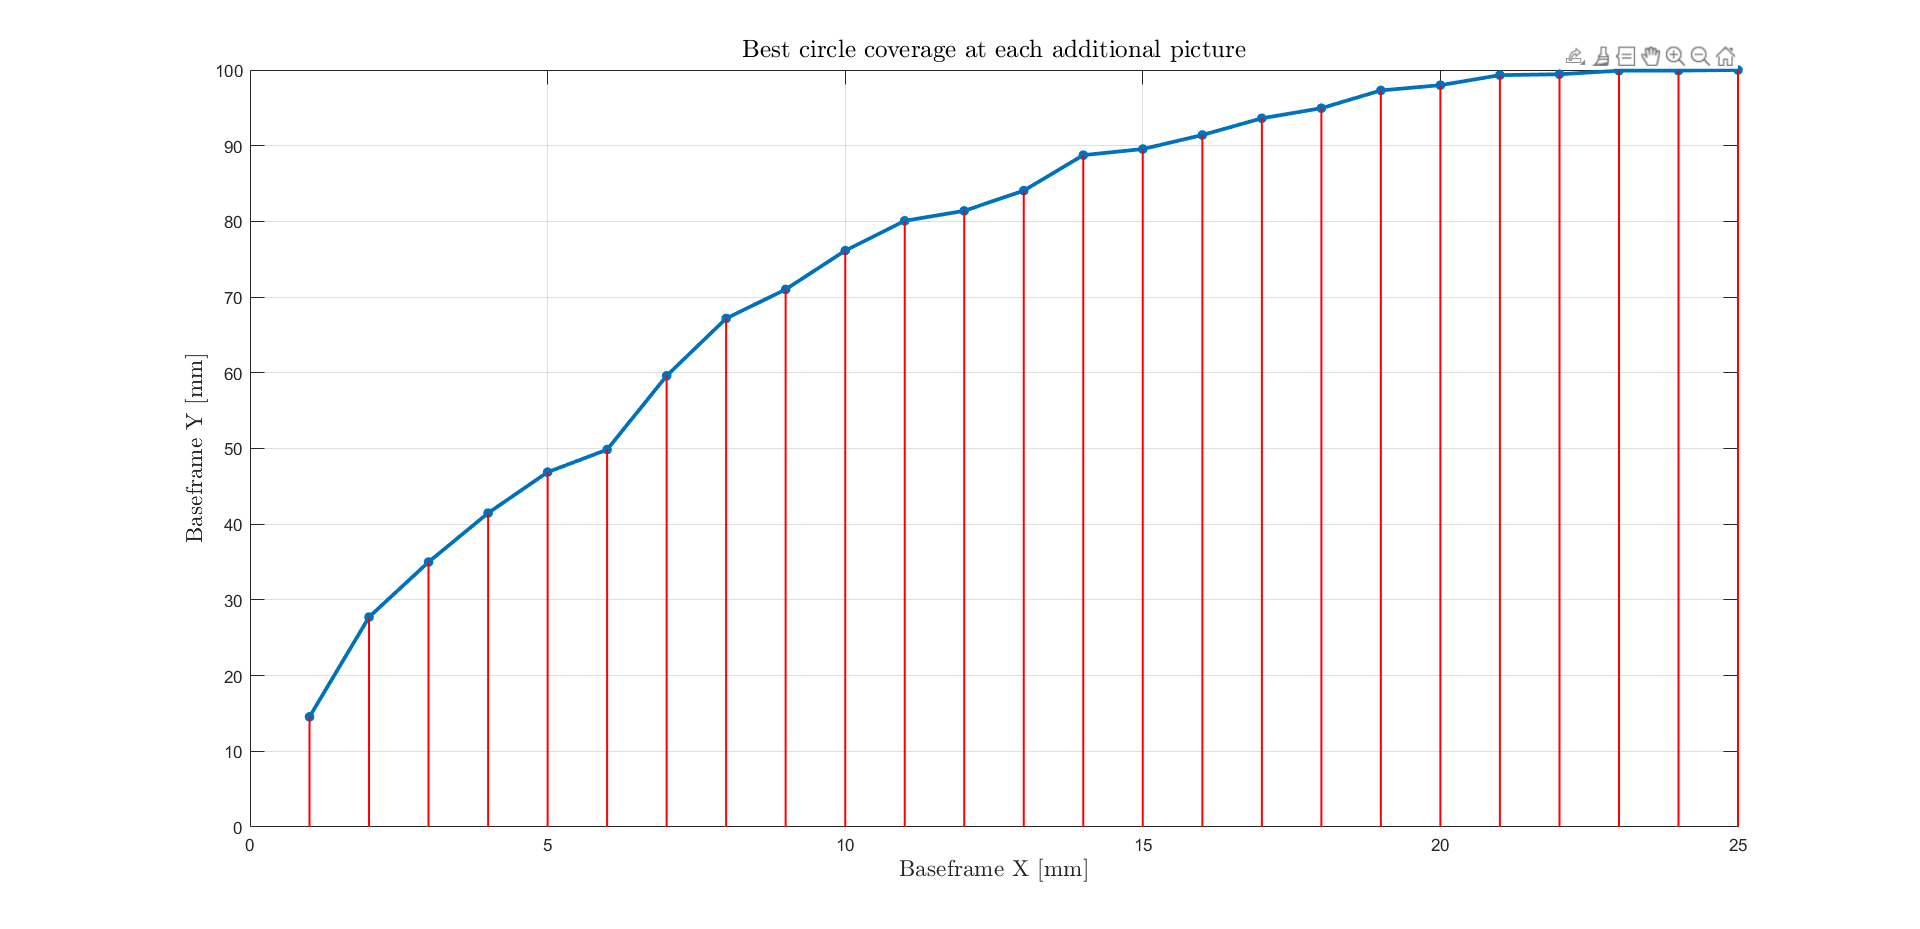

clf
figure(102)
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
plot(area_dist_sorted, '.-','MarkerSize', 20,'LineWidth',2.25)
title('Best circle coverage at each additional picture','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
zlabel('Baseframe Z $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
grid on
box on

filename = 'best_area.gif';

hold on    
for n = 1:size(area_dist_sorted, 1)
    
    hold on
    plot([n, n], [0, area_dist_sorted(n)], 'r-', 'LineWidth', 1.2)
    
    drawnow
    frame = getframe;
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,128);
    if n == 1;
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
end